# form generation

clear all
%{
To generate a shape use alpha shape to make overall structure
%}

%%Wire Properties%% [Metric]
diameter = 1.29; %[mm]
barrel = 12,7; %[mm]

barrel = 12



%{
x is the points on the x axis
y is the points on the y axis

%}

x=[0;0;20;20]; %points in mm
y=[0;5;5;0]; %point in mm
smoothing=30; %smoothing of the shape

shp=alphaShape(x,y,smoothing);
plot(shp)
hold on
xlabel("distance x [mm]")
ylabel("distance y [mm]")
xmin=min(x);
xmax=max(x);
ymin=min(y);
ymax=max(y);
xlim([xmin,xmax]);
ylim([ymin,ymax]);
[X,Y]=meshgrid((xmin:diameter:xmax),(ymin:diameter:ymax))

X =          0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500
         0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500
         0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500
         0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500


Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900
    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800
    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700


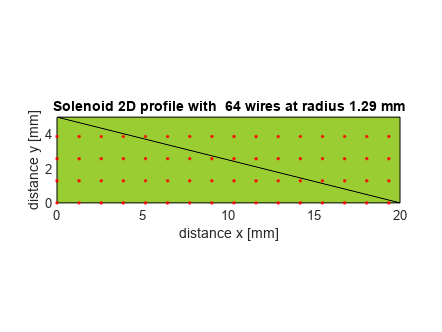


in = inShape(shp,X,Y);
plot(X(in),Y(in),'r.')
plot(X(~in),Y(~in),'b.')
title(['Solenoid 2D profile with  ',num2str(sum(in,"all")),' wires at radius ', num2str(sum(diameter)), ' mm'])


%First plot done with shape and wires in solenoid shape


# 3d model generation

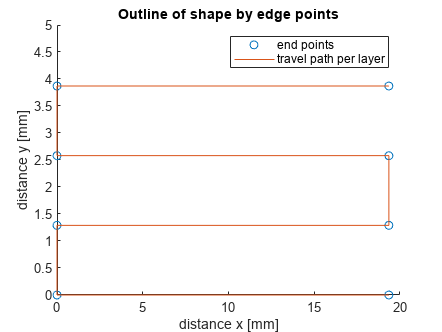



%{
goal is to use the in matrix as a guide of where the turns are per layer
and generate a unique solution to build the shape with the jumping turns
between layers
%}

%{
concept first layer will continue to have turns until logical matrix is
zero 

then as it jumps it will go simply up one and then work backwards to the
other end of the shape so the winding will look like the concept below for
the turns

    ------>|  over x end
  ^           up x
  |<-------  ...
          ^  up 1
--------->| over 1
%}

%{
for # of vertical layers (y)
    select at that layer:
    if odd {
        first point (x1#,y1#)
        Second point (x2#,y2#)
    } else
    {
        first point (x2#,y2#)
        Second point (x1#,y1#)
    }
        generate # of turns by (first-second)

    %%at this point layer # is completed in neccesary direction
    if(next layer [#+1 contains an 1 in {in}])
        determine lateral distance
        and vertical distance
        if odd {
            dist_lateral=(x2{#+1}-x1#)
            dist_vert=(y2{#+1}-y1#)
        }else{
            dist_lateral=(x1{#+1}-x2#)
            dist_vert=(y1({#+1}-11#)
        }
    generate layer between turn    
%}

sz=size(in);
layers_max=sz(1,1);
turn_max=sz(1,2);

x_points=zeros(1,1); %x point storage matrix
y_points=zeros(1,1); %y point storage matrix
dist=zeros(1,1); %dist  storage matrix
turns=zeros(1,1); %#of turns storage matrix

point_count=1;
for layer=1:1:layers_max %for all vertical layers
    if(rem(layer,2)==0) %for even layers

        for index=1:1:(turn_max) %start at low index and go over
            if(in(layer,index)==1) %find first point when in is 1
                first=[index,layer];
                break
            end
        end

        for index=(turn_max):-1:1 %start at high index and go back
            if(in(layer,index)==1)
                second=[index,layer];
                break
            end
        end
    %end of even layers
    else %for odd layers

        for index=1:1:(turn_max) %start at low index and go over
            if(in(layer,index)==1) %find first point when in is 1
                second=[index,layer];
                break
            end
        end

        for index=(turn_max):-1:1 %start at high index and go back
            if(in(layer,index)==1)
                first=[index,layer];
                break
            end
        end

    end %end odd layers
    x_point(1,point_count)=first(1,1);
    y_point(1,point_count)=first(1,2);
    point_count=point_count+1; %increment count
    x_point(1,point_count)=second(1,1);
    y_point(1,point_count)=second(1,2);
    point_count=point_count+1; %increment count
    turns(1,layer)=second(1,1)-first(1,1); %calculate # of turns per layer

    

    if(second(1,1)>first(1,1))
        turns(1,layer)=turns(1,layer)+1;
        dist(1,layer)=turns(1,layer).*1.29-1.29; %update into measured length
    else
        turns(1,layer)=turns(1,layer)-1;
        dist(1,layer)=turns(1,layer).*1.29+1.29; %update into measured length
    end

end
x_edges=(x_point-1).*diameter;
y_edges=(y_point-1).*diameter;
figure()
scatter(x_edges,y_edges)
xlabel("distance x [mm]")
ylabel("distance y [mm]")
title("Outline of shape by edge points")
xlim([xmin,xmax]);
ylim([ymin,ymax]);
hold on
plot(x_edges,y_edges)
legend('end points','travel path per layer')


%{
X_point and y_point are still based upon the in matrix and do not have any
distance calibration

x_edge and y_edge are converterted to distance

determine number of turns between points 1,2 and then jump to 3 iteratively

dist is from dist list
 %# turns= dist/diameter

%}

# plotting of overall shape of solenoid

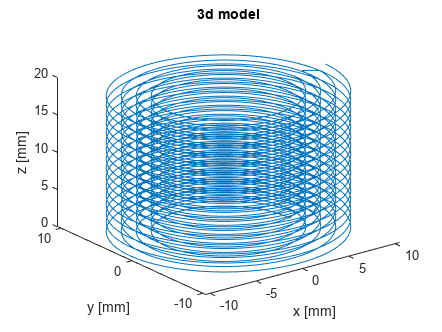

num_points=1:1000; %num points per layer
figure()



X_sol=zeros(1);
Y_sol=zeros(1);
Z_sol=zeros(1);


sol_r=(barrel/2)+diameter/2;%calculate wire diameter for first layer
for layer=1:1:layers_max %for each layer
    x_sol=sol_r.*cos(2.*pi.*(num_points/length(num_points)).*turns(1,layer)); %x radius solenoid diameter * cos (2pi*num_turn*(point)/(max points))
    y_sol=sol_r.*sin(2.*pi.*(num_points/length(num_points)).*turns(1,layer)); %y radius solenoid diameter * cos (2pi*num_turn*(point)/(max points))
    
    if(x_edges(1,(layer*2)-1)==x_edges(1,(layer*2))) %catch overlaps
        z_sol=x_edges(1,(layer*2))+diameter./num_points;
    else
        z_sol=x_edges(1,(layer*2)-1):dist(1,layer)/(length(num_points)-1):x_edges(1,(layer*2)); %vertical height steps, fails on single turns, caught by if
    end

    sol_r=sol_r+diameter; %increment diameter

    %straight jump between layers for ease of design
    if(layer==1) %first layer assign
        X_sol=x_sol;
        Y_sol=y_sol;
        Z_sol=z_sol;
    else %other layer append
        X_sol=[X_sol x_sol];
        Y_sol=[Y_sol y_sol];
        Z_sol=[Z_sol z_sol];
    end
     
end
    plot3(X_sol,Y_sol,Z_sol)
    hold on
    xlabel("x [mm]")
    ylabel("y [mm]")
    zlabel("z [mm]")
    title("3d model")


    figure()
    plot(X_sol(ceil(end/2), :),Z_sol(ceil(end/2), :))
    title("2d cross section")
    xlabel("x [mm]")
    ylabel("y [mm]")

    clearvars first second index layer sol_r smoothing sz x y X Y x_points y_points



# 3d fields    

%all sections  below
clear xmax ymax x_sol y_sol z_sol

xmax=max(X_sol);
ymax=max(Y_sol);
zmax=max(Z_sol);


# Inputs


%Inputs
current=300;%amps
s=1.5; %scaling of overall volume
d=2;  %step distance mm

%points around solenoid for points
[RX,RY,RZ]=meshgrid(-d*round(s*xmax/d):d:d*round(s*xmax/d),-d*round(s*ymax/d):d:d*round(s*ymax/d),-d*round(s*zmax/d):d:d*round(s*zmax/d));

%scale down to M

RX=RX/1000;
RY=RY/1000;
RZ=RZ/1000;

X_sol=(X_sol)/1000;
Y_sol=(Y_sol)/1000;
Z_sol=(Z_sol)/1000

Z_sol =     0.0194    0.0193    0.0193    0.0193    0.0193    0.0193    0.0192    0.0192    0.0192    0.0192    0.0192    0.0191    0.0191    0.0191    0.0191    0.0191    0.0190    0.0190    0.0190    0.0190    0.0190    0.0189    0.0189    0.0189    0.0189    0.0189    0.0188    0.0188    0.0188    0.0188    0.0188    0.0187    0.0187    0.0187    0.0187    0.0187    0.0187    0.0186    0.0186    0.0186    0.0186    0.0186    0.0185    0.0185    0.0185    0.0185    0.0185    0.0184    0.0184    0.0184



xmax=max(X_sol);
ymax=max(Y_sol);
zmax=max(Z_sol);

%R points of calculation
R = [RX(:),RY(:),RZ(:)]

R =    -0.0160   -0.0160   -0.0300
   -0.0160   -0.0140   -0.0300
   -0.0160   -0.0120   -0.0300
   -0.0160   -0.0100   -0.0300
   -0.0160   -0.0080   -0.0300
   -0.0160   -0.0060   -0.0300
   -0.0160   -0.0040   -0.0300
   -0.0160   -0.0020   -0.0300
   -0.0160         0   -0.0300
   -0.0160    0.0020   -0.0300



%inputs to matlab magnetic funciton data

%https://www.mathworks.com/matlabcentral/fileexchange/48990-magnetic-field-simulator

%from data start point of length
from=zeros(0);
%to data end point of length
to=zeros(0);
%CUR data of current at length
cur=zeros(0);



%fill in solenoid data for current paths
for index=1:length(Z_sol)-1 %index through all points;
    %filling form data
    from(index,1:3)=[X_sol(1,index),Y_sol(1,index),Z_sol(1,index)];
    %filling to data
    to(index,1:3)=[X_sol(1,index+1),Y_sol(1,index+1),Z_sol(1,index+1)];
    %filling cur data
    cur(index,1)=current;
end

Hmat = magnetic_field( from, to, cur, R )

Hmat = 1.0e+05 *

    0.0049    0.0052    0.0070
    0.0052    0.0049    0.0077
    0.0056    0.0045    0.0083
    0.0059    0.0040    0.0090
    0.0062    0.0034    0.0095
    0.0064    0.0027    0.0100
    0.0065    0.0020    0.0103
    0.0067    0.0012    0.0105
    0.0067    0.0003    0.0106
    0.0067   -0.0005    0.0106


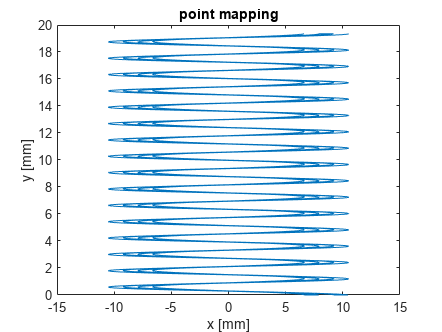


clear index x y z
title("point mapping")

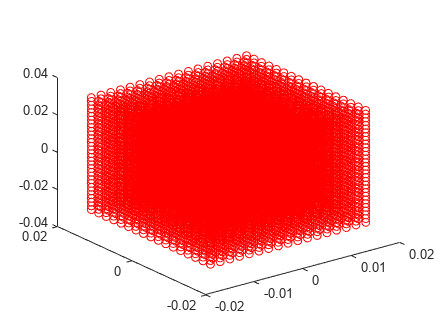

plot3(R(:,1),R(:,2),R(:,3),"or")

% xlim([-xmax, xmax])
% ylim([-ymax, ymax])
% zlim([-zmax, zmax])

figure()
q=quiver3(R(:,1),R(:,2),R(:,3),Hmat(:,1),Hmat(:,2),Hmat(:,3))

q =   Quiver with properties:

        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [8959×1 double]
        YData: [8959×1 double]
        ZData: [8959×1 double]
        UData: [8959×1 double]
        VData: [8959×1 double]
        WData: [8959×1 double]

  Show all properties


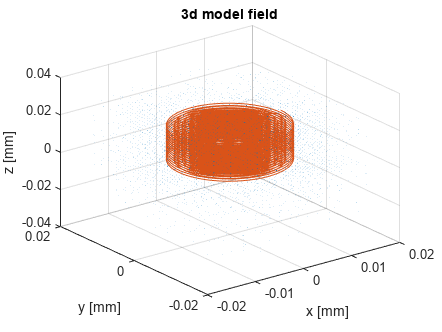

q.MarkerSize=20;
hold on
plot3(X_sol,Y_sol,Z_sol)
hold off
xlabel("x [mm]")
ylabel("y [mm]")
zlabel("z [mm]")
title("3d model field")
%field is seemingly working need to generate force generation
hold off

# Acceleration, Velocity Mapping

clear dl hx hy hz HX HY HZ layers_max nun_points point_count r r_hat s step turn_max turns X Y Z x_edges x_point x_sol X_Sol x_step y_sol Y_Sol z_sol Z_Sol


# inputs


projectile_r=6.35; %entry in mm
projectile_l=50; %length of projectile mm
offset=20; %offset from top of solenoid mm
density_B=7300*(1/1000)^3; %kg/mm^3
m_p=4.89; %Joule/Tesla
u0=4*pi*10^(-7); %permability
mass=pi*((projectile_r)^2)*projectile_l*density_B;

# projectile

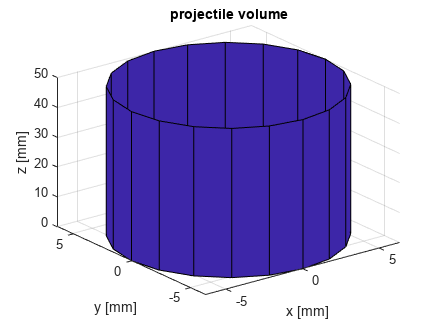


[PX,PY,PZ]=cylinder(projectile_r);
surf(PX,PY,PZ*projectile_l);
title("projectile volume");
xlabel("x [mm]");
ylabel("y [mm]");
zlabel("z [mm]");

# force calculation

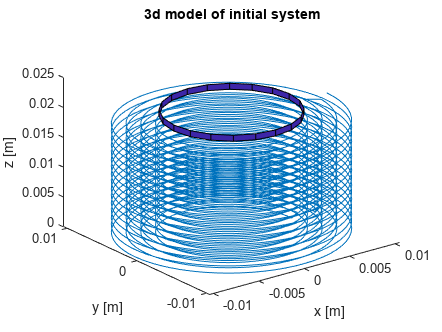

%need to step projectile from initial offset and then calculate velcoity, 
PX=PX*0.001;
PY=PY*0.001;
PZ=PZ*0.001+offset/1000;
plot3(X_sol,Y_sol,Z_sol)
hold on
surf(PX,PY,PZ);
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
title("3d model of initial system")
hold off

%deterimine B-field within system
U_B=zeros(length(R),3); %energy product within overall volume
for index=1:size(R,1) %into index of columns of R
    if(R(index,3)<=max(PZ,[],"all") && R(index,3)>=min(PZ,[],"all")) %if within projectile vertically
            if sqrt(R(index,1).^2+R(index,2).^2)<=(projectile_r/1000) %if within cylinder radius
               U_B(index,1:3)=m_p*Hmat(index,1:3)*u0; %assign if within cylinder
            end

    end
end

q=quiver3(R(:,1),R(:,2),R(:,3),U_B(:,1),U_B(:,2),U_B(:,3))

q =   Quiver with properties:

        Color: [0 0.4470 0.7410]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [8959×1 double]
        YData: [8959×1 double]
        ZData: [8959×1 double]
        UData: [8959×1 double]
        VData: [8959×1 double]
        WData: [8959×1 double]

  Show all properties


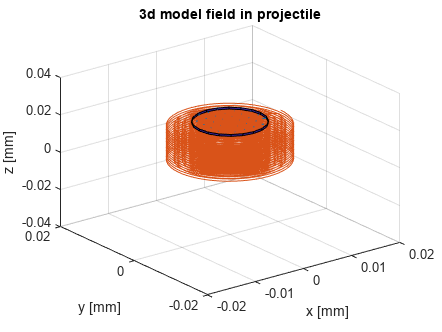

q.MarkerSize=20;
hold on
surf(PX,PY,PZ);
plot3(X_sol,Y_sol,Z_sol)
hold off
xlabel("x [mm]")
ylabel("y [mm]")
zlabel("z [mm]")
title("3d model field in projectile")

# Matlab magnetic field function

function Hmat = magnetic_field( FROM, TO, CUR, R )
% The function computes the magnetic field H induced by a given conductors
% geometry. The geometry is represented by straight conductors ("current sticks").
% Theory of this numerical technique may be found in
% "Electromagnetic fields and Energy" by Hermann A. Haus, page 322.
%
% Written by Prof. Yoash Levron, Technion, Israel, 2014.
%
% FUNCTION INPUTS
%
% The shape of conductors is represented by "current sticks". For example,
% a square conductor is represented by four sticks.
%
% FROM - an array of vector points indicating where each current
% stick starts. FROM(i,:) is a raw vector (x,y,z), indicating a
% point in 3-D space.  Units in meters [m]
%
% TO - same as FROM. Indicating where each current stick ends.
%
% CUR - Column Vector representing the current of each stick. CUR(i)is
% a scalar. Units in Amperes [A]
%
% R - Observation points. An array of vector points in which the magnetic
% field is to be calculated. R(i,:) is a raw vector (x,y,z), indicating a
% point in 3-D space. Units in meters [m]
%
% FUNCTION OUTPUT
%
% Hmat - the magnetic field H at the observation points. Hmat(i,:) is a
% raw vector (Hx,Hy,Hz), indicating the magnetic field vector in Cartesian
% coordinates. Units are [A/m].
%%%%%%%%%%%%%%%%%%%%% COMPUTATION  %%%%%%%%%%%%%%%
Hmat = 0*R;  % initialize field matrix
% For each stick compute the field at all observation points
    for ii = 1:length(CUR)
        from1 = FROM(ii,:);
        to1 = TO(ii,:);
        cur1 = CUR(ii);
        B = repmat(from1,size(R,1),1) - R;
        C = repmat(to1,size(R,1),1) - R;
        A = C - B;
    
        crs = cross(C,A,2);   % cross product   
        temp1 = (cur1/(4*pi))*( dot(A,C,2)./(sum(C.^2,2).^0.5) - ...
            dot(A,B,2)./(sum(B.^2,2).^0.5) )./sum(crs.^2,2);
    
        Hpp = crs.*repmat(temp1,1,3);
    
        Hmat = Hmat + Hpp;
    end
end